## AAE334 HW7 MATLAB CODE

clear all; close all; clc;

fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE334\matlab\outputs\HW7';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

### problem 1-a

% Defining necessary properties
v_inf = 13.4;  % freestream velocity [m/s]
rho_inf = 1.225;  % freestream air density [kg/m3]
q_inf = 0.5*rho_inf*v_inf^2;  % freestream dynamic pressure [Pa]
S_w = 0.86;  % wing area [m2]
S_t = 0.208;  % tail area [m2]
ch_w = 0.36;  % chord length of wing [m]
ch_t = 0.241;  % chord length of tail [m]
l = 1.016;  % distance from the LE of the wing to the LE of the tail [m]
ch_mean = ch_w;  % mean chord length of the wing [m]
epsilon = 0;
e_a = 0.4;  % D(epsilon)/Da
W = 46.71;  % weight of the plane [N]

% Calculating the x_cg (center of gravity of the plane)

% Necessary angles [rad]
a_zl = deg2rad(-2.1)  % zero lift angle

a_zl = -0.0367

i_w = deg2rad(4.5)  % incident angle of the wing

i_w = 0.0785

i_t = i_w - deg2rad(2)  % incident angle of the tail wrt the plane

i_t = 0.0436


% find a, C_Lw, and C_Lt
[C_Lw, C_Lt, a] = CLw_CLt_AoA(W, i_w, i_t, q_inf, S_w, S_t)

C_Lw = 0.3550

C_Lt = 0.5743

a = 0.1350

a_a = a - a_zl  % absolute angle of attack

a_a = 0.1717


% the lifts for the wing and tail 
L_w = q_inf*S_w*C_Lw  % wing [N]

L_w = 33.5728

L_t = q_inf*S_t*C_Lt  % tail [N]

L_t = 13.1372


% aerodynamic center positions (wrt the LE of the wing)
xhat_ac_w = ch_w/4  % wing [m]

xhat_ac_w = 0.0900

xhat_ac_t = ch_t/4  % tail [m]

xhat_ac_t = 0.0603

lh = l*cos(a_a + i_t);
x_ac_w = xhat_ac_w*cos(a_a + i_w)  

x_ac_w = 0.0872

x_ac_t = lh + xhat_ac_t*cos(a_a + i_t)

x_ac_t = 1.0514

x_ac_til = 0.25;

% moment coefficient about the aerodynamic center of the wing 
C_Mac_w = -0.05;  
% moment about the aerodynamic center of the wing [N-m]
Mac_w = q_inf*S_w*ch_mean*C_Mac_w

Mac_w = -1.7025


% solve
syms var1
eqn1 = Mac_w + L_w*(var1 - x_ac_w) - L_t*(x_ac_t - var1) + W*var1 == 0;
x_cg = double(solve(eqn1, var1))

x_cg = 0.1974


x_cg_til = x_cg/ch_mean

x_cg_til = 0.5484

% C_La
C_La_w = C_Lw/a_a

C_La_w = 2.0675

% C_La_t
C_La_t = C_Lt/(a_a)

C_La_t = 3.3450

% l_t distance from the x_cg to the aerodynamic center of the tail
l_t = x_ac_t - x_cg

l_t = 0.8540

% Vh
Vh = S_t*l_t/S_w/ch_mean

Vh = 0.5737

% C_Mo
C_Mo = C_Mac_w + C_La_t*(epsilon + i_t)*Vh

C_Mo = 0.0337

% C_Ma
C_Ma = C_La_w*(x_cg_til - x_ac_til) - C_La_t*(1 - e_a)*Vh

C_Ma = -0.5346

% x_n
x_n_til = x_ac_til + C_La_t/C_La_w*(1 - e_a)*Vh

x_n_til = 0.8069

x_n = x_n_til*ch_mean

x_n = 0.2905

% SM
SM = x_n_til - x_cg_til

SM = 0.2586

### problem 1-b

% importing data
data_1b = readmatrix("inputs\hw7\hw7_Cm_vs_Cl_case1_2_2.csv");
% Calculating the static margin 
SM_1b = calc_SM_from_xflr(data_1b)

SM_1b = 0.2075

% Importing another data
data_1b2 = readmatrix("inputs\hw7\hw7_Cm_vs_alpha_case1_2.csv");
% Calculating the C_M0 (*for the angle of attack add 2.1 degrees to adjust
% to the absolute angle of attack)
[C_Mo_1b, C_Ma_1b] = calc_CMo_and_CMa_from_xlfr(data_1b2, -2.1, rad2deg(i_w))

C_Mo_1b = 0.1185

C_Ma_1b = -0.0179

### problem 2-a

% importing data
data_2a = readmatrix("inputs\hw7\hw7_Cm_vs_Cl_case2a.csv");
% Calculating the static margin 
SM_2a = calc_SM_from_xflr(data_2a)

SM_2a = 0.1369

% Importing another data
data_2a2 = readmatrix("inputs\hw7\hw7_Cm_vs_alpha_case2a.csv");
% Calculating the C_M0 (*for the angle of attack add 2.1 degrees to adjust
% to the absolute angle of attack)
[C_Mo_2a, C_Ma_2a] = calc_CMo_and_CMa_from_xlfr(data_2a2, -2.1, rad2deg(i_w))

C_Mo_2a = 0.0368

C_Ma_2a = -0.0122

% find a, C_Lw, and C_Lt
q_inf_2a = 245;
[C_Lw_2a, C_Lt_2a, a_2a] = CLw_CLt_AoA(W, i_w, i_t, q_inf_2a, S_w, S_t)

C_Lw_2a = 0.1358

C_Lt_2a = 0.3551

a_2a = 0.1002

a_a_2a = a_2a - a_zl  % absolute angle of attack

a_a_2a = 0.1368


% the lifts for the wing and tail 
L_w = q_inf_2a*S_w*C_Lw_2a  % wing [N]

L_w = 28.6129

L_t = q_inf_2a*S_t*C_Lt_2a  % tail [N]

L_t = 18.0971

### problem 2-b

% importing data
data_2b = readmatrix("inputs\hw7\hw7_Cm_vs_Cl_case2b.csv");
% Calculating the static margin 
SM_2b = calc_SM_from_xflr(data_2b)

SM_2b = 0.2009

% Importing another data
data_2b2 = readmatrix("inputs\hw7\hw7_Cm_vs_alpha_case2b.csv");
% Calculating the C_M0 (*for the angle of attack add 2.1 degrees to adjust
% to the absolute angle of attack)
[C_Mo_2b, C_Ma_2b] = calc_CMo_and_CMa_from_xlfr(data_2b2, -2.1, rad2deg(i_w))

C_Mo_2b = 0.0561

C_Ma_2b = -0.0180

% find a, C_Lw, and C_Lt
q_inf_2b = 245;
[C_Lw_2b, C_Lt_2b, a_2b] = CLw_CLt_AoA(W, i_w, i_t, q_inf_2b, S_w, S_t)

C_Lw_2b = 0.1358

C_Lt_2b = 0.3551

a_2b = 0.1002

a_a_2b = a_2b - a_zl  % absolute angle of attack

a_a_2b = 0.1368


% the lifts for the wing and tail 
L_w = q_inf_2b*S_w*C_Lw_2b  % wing [N]

L_w = 28.6129

L_t = q_inf_2b*S_t*C_Lt_2b  % tail [N]

L_t = 18.0971

## Plotting

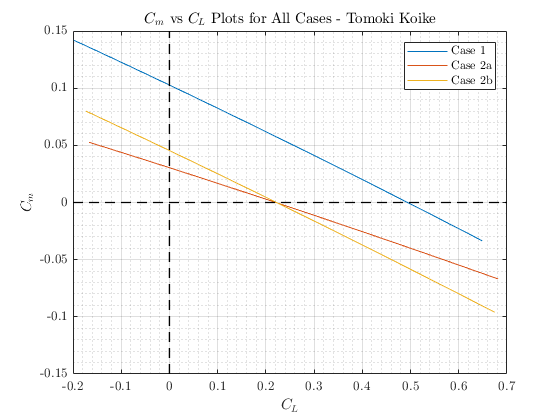

fig1 = figure("Renderer","painters");
plot(data_1b(:,1),data_1b(:,2))
title({'$C_m$ vs $C_L$ Plots for All Cases - Tomoki Koike'})
xlabel('$C_L$')
ylabel('$C_m$')
hold on
plot(data_2a(:,1),data_2a(:,2))
plot(data_2b(:,1),data_2b(:,2))
plot(linspace(-0.2,0.7,100),zeros([1,length(linspace(-0.2,0.7,100))]),'--k',"LineWidth",1.0)
plot(zeros([1,length(linspace(-0.15,0.15,100))]),linspace(-0.15,0.15,100),'--k',"LineWidth",1.0)
hold off
grid on; grid minor; box on;
legend('Case 1','Case 2a','Case 2b')
saveas(fig1, fullfile(fdir,'Cm_vs_Cl.png'))

### FUNCTIONS

function SM = calc_SM_from_xflr(data)
    % data: data points
    CL_1b = data(:,1);
    Cm_1b = data(:,2);
    
    % SM
    if Cm_1b(CL_1b == min(abs(CL_1b)))
        Cm_1b_0 = Cm_1b(CL_1b == min(abs(CL_1b)));
    else
        Cm_1b_0 = Cm_1b(CL_1b == -(min(abs(CL_1b))));
    end 
    
    if CL_1b(Cm_1b == -(min(abs(Cm_1b))))
        CL_1b_0 = CL_1b(Cm_1b == -(min(abs(Cm_1b))));
    else
        CL_1b_0 = CL_1b(Cm_1b == (min(abs(Cm_1b))));
    end
    SM = Cm_1b_0/CL_1b_0;
end

function [C_Mo, C_Ma] = calc_CMo_and_CMa_from_xlfr(data, a_zl, i_w)
    % data: data points
    % a_zl: zero lift angle of attack
    % i_w: wing incidence angle
    Cm = data(:,2);
    a = data(:,1) - a_zl + i_w;
    
    P = polyfit(a,Cm,1);
    C_Ma = P(1);
    C_Mo = P(2);
end

function [C_Lw, C_Lt, a] = CLw_CLt_AoA(W, i_w, i_t, q_inf, S_w, S_t)
    % system equations to find a, C_Lw, and C_Lt
    syms x1 x2 x3
    eqn1 = x1 == 2*pi*(x3 - i_w);
    eqn2 = x2 == 2*pi*(x3 - i_t);
    eqn3 = W == q_inf*(S_w*x1 + S_t*x2);
    res = solve([eqn1 eqn2 eqn3],[x1 x2 x3]);
    % the lift coefficients for the wing and tail respectively
    C_Lw = double(res.x1);
    C_Lt = double(res.x2);
    % angle of attack
    a = double(res.x3);
end